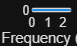

% --- ดึงข้อมูลจาก timeseries ---
t = adc_clean.Time(:);
y = double(adc_clean.Data(:));

% --- เลือกช่วงที่ต้องการ (ตัวอย่าง: 1–199 s) ---
t_start = 1;
t_end   = 199;
idx = (t >= t_start) & (t <= t_end);
t_seg = t(idx);
y_seg = y(idx);

% --- หาค่าเฉลี่ยของข้อมูลดิบโดยตรง ---
mean_raw = mean(y_seg);

% --- แสดงผล ---
fprintf('ช่วง %.0f–%.0f s → ค่าเฉลี่ย = %.4f\n', t_start, t_end, mean_raw);